Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# Super-conducting dipole defined by intersecting circles (Section 4.4.2)

Volker Ziemann, 211110, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

In Section 4.4.1 we found that a current distribution that has the form of two intersecting circles produces a dupole field in the inside region. We therefore define two circles `C1` and `C2`, displaced horizontally by $\pm5$ cm and having a radius of $0.5$ m, enclosed in a square `World` with 2 m to each side and defined as a polygon.

clear all; close all
C1=[1;0.05;0;0.5;zeros(6,1)];
C2=[1;-0.05;0;0.5;zeros(6,1)];
World=[2;4; -1;1;1;-1;-1;-1;1;1]; 

Then we assemble the geometry g, create the model and add the geometry to it.

gd=[World,C1,C2];  % assemble geometry
ns=char('World','C1','C2')';  % names of the regions                 
sf='World+(C1-C2)'; 
g=decsg(gd,sf,ns);
model=createpde(1);
geometryFromEdges(model,g);

At this point, we display the EdgeLabels, which allows us to set` u =` $A_z$ on the outer limits of the World to zero.

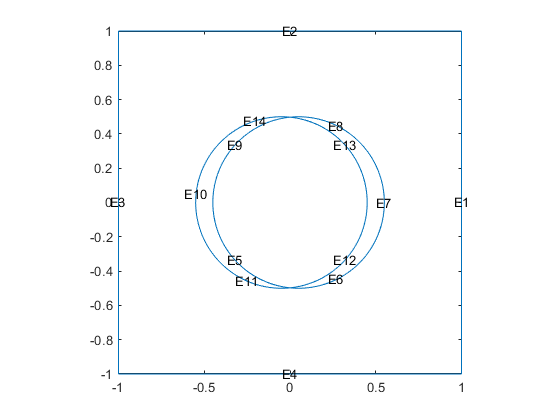

pdegplot(model,'EdgeLabels','on'); axis square;

applyBoundaryCondition(model,'Edge',[1:4],'u',0);

The material is specified to have permeability $\mu_r=1$ everywhere and the current correpsonding to f=100 is approximately $80 \times 10^6$ A/m^2.

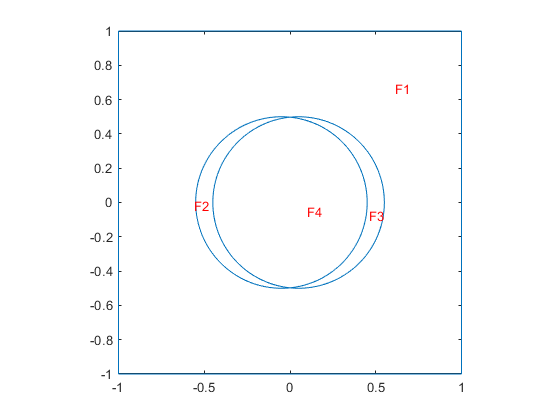

figure; 
pdegplot(model,'SubDomainLabels','on'); axis square;

specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',[1,4]);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',100,'Face',2);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',-100,'Face',3);

In the next step we mesh the geometry and siplay the mesh.

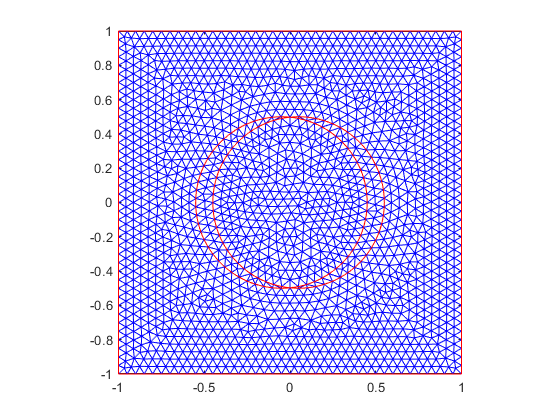

figure; 
generateMesh(model,'Hmax',0.05);
pdemesh(model); axis square;

Now we are ready to solve the probelm with a call to `solvepde(),` which returns a structure `result` with all the useful properties of the solution included. We immediately use it to plot the potential u = $A_z$, which is available as member `NodalSolution` in the structure `result`.

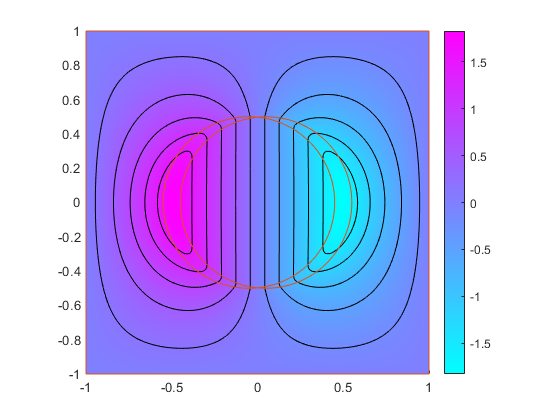

result=solvepde(model);
figure; 
pdeplot(model,'xydata',result.NodalSolution,'contour','on'); 
hold on; pdegplot(model)

The gradients are also available in result, and we use them to determine the magnetic fields from Equation 4.10. We then plot $B_y$ in the region and find that the field reaches almost 4 T.  

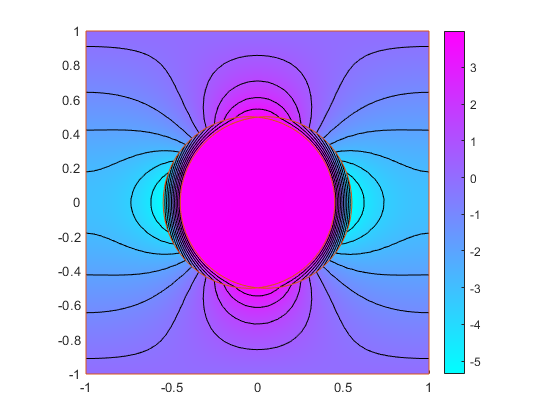

By=-result.XGradients; 
Bx=result.YGradients; 
figure; pdeplot(model,'xydata',By,'contour','on'); 
hold on; pdegplot(model); 

We then investigate the homogeneity of the field by plotting $B_y$ along a line in the midplane of the magnet. 

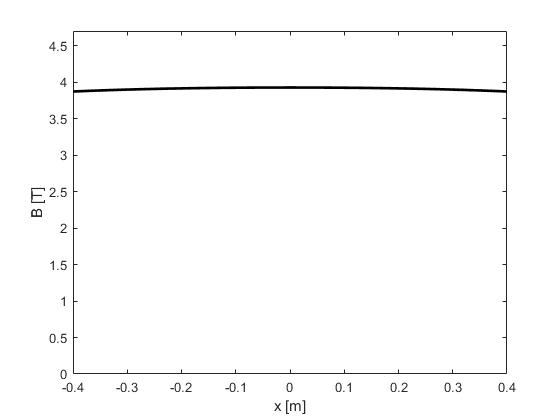

x=-0.4:0.01:0.4; y=zeros(1,length(x));
[dAx,dAy]=evaluateGradient(result,x,y); Bx=dAy; By=-dAx; B=hypot(Bx,By);
figure; plot(x,By,'k','LineWidth',2); 
xlabel('x [m]'); ylabel('B [T]'); ylim([0,4.7]);